# Building Management System Requirement Analysis

Copyright 2024 The MathWorks, Inc.

This Live Script contains the steps to read building data, parameterize the model, and run the simulation. You will learn how to calculate energy requirements for maintaining the building at a set point temperature. In this example, the **Control** subsystem provides energy to the **Building** custom component through the port **S** to maintain the building temperature at a desired setpoint value. No heat pump, room radiator, or underfloor heating or cooling are modelled. Based on the solar load and changes in ambient temperature, the energy required to keep building at the setpoint temperature is calculated. The model is run at fixed hourly-timestep.

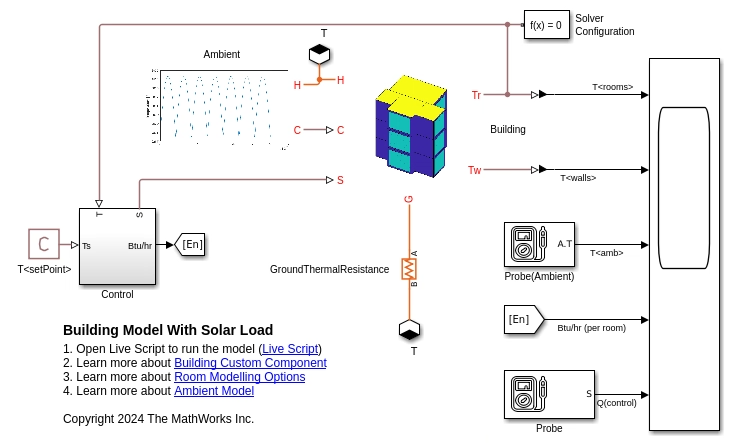

## Read Building Data

Load the building data with solar load from the XML file.

[apartment3D, geoLocation, dateTimeVec] = ...
    readBuildingDataXML(FileName="building_with_solar_load.xml");

    {'Location:Bengaluru'}

Simulation Duration:
*** Start Time :01-May-2024 01:00:00
*** End Time   :07-May-2024 01:00:00
*** Room Names in Building : FireExit,Bathroom,Kitchen,Bedroom,LivingRoom


Set viewing direction for all 3D plots.

viewingAngle = [-1 -1 1]; 

Create an icon for the building custom model in Simscape.

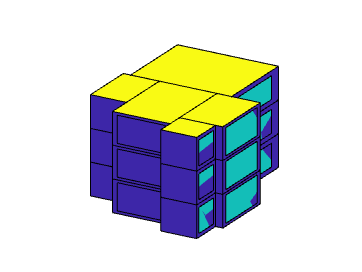

createIconBuildingCustomComponent(Building=apartment3D,...
                                  PlotViewDirection=viewingAngle);

## Parameterize Model

### Ambient Temperature Model

Get parameters for sunrise time, sunset time, and a list of days for the simulation, from the apartment3D struct generated above.

[opsParams.listOfDays,...
    opsParams.simStartTime,...
    opsParams.sunrise,...
    opsParams.sunset] = ...
    getAmbientTemperatureVariationModelData(DateTimeVector=dateTimeVec,...
                                            Location=geoLocation);

Specify the average day-time temperatures, average night-time temperatures, and the percentage variation of temperature from the average. You must provide these average temperatures for all days, as included in the building data XML part file.

opsParams.averageDayTvec   = 303*ones(1,length(opsParams.listOfDays));
opsParams.averageNightTvec = 299*ones(1,length(opsParams.listOfDays));
opsParams.percentDayTvar   = 1;
opsParams.percentNightTvar = 1;

Set the desired temperature operating point for the building rooms.

opsParams.desiredTempSetPoint = 293;

Estimate the initial ambient temperature based on the simulation start time.

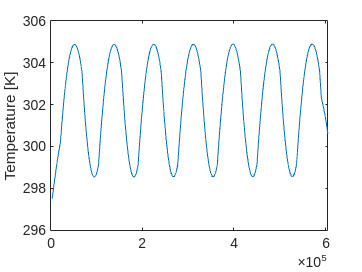

[t,Tamb] = createIconAmbientCustomComponent(AvgDayTemperatureVec=opsParams.averageDayTvec,...
                                            PercentDayTemperatureVar=opsParams.percentDayTvar,...
                                            AvgNightTemperatureVec=opsParams.averageNightTvec,...
                                            PercentNightTemperatureVar=opsParams.percentNightTvar,...
                                            SunriseVec=opsParams.sunrise,...
                                            SunsetVec=opsParams.sunset);

opsParams.initialTemperature = round(interp1(t,Tamb,hour(dateTimeVec(1,1)),"nearest","extrap"),1);

disp(strcat('Initial Temperature = ',num2str(opsParams.initialTemperature),'K'));

Initial Temperature =297.5K


clear t Tamb

### Building Component

params = getParamsForSimscapeComponent(Building=apartment3D);

Set the building to ground thermal resistance value.

opsParams.groundThermalResistance = 100;

Specify the modelling option. For requriement analysis, select `Thermal Requirements`. For more information on the `Thermal Management: Radiator Model`, or `Thermal Management: Under Floor Model`, or `Thermal Management: Radiator and Under Floor Model`, options, see [Simulate Building Energy Management System](matlab:open('./SimulateBuildingEnergyManagement.mlx')).

roomModelOption = "roomPhysicsOptions.requirements";

Set simulation runtime. It must be less than or equal to the total time specified in **dateTimeVec**.

opsParams.simRunTime = 3600*24*7; % time in seconds

Set the parameters for the building custom component.

mdl = setParametersForBuildingCustomComponent(Building=apartment3D,...
                                              BuildingNetworkData=params,...
                                              PhysicsTableData=opsParams,...
                                              RoomModel=roomModelOption);

Parameterized Model :BuildingModelWithSolarLoad.slx
*** Simulation Time = 145-hours
*** Model Parameterized for Time =145-hours
*** Solver :Fixed-step (ode1be)


## Run Simulation

Open the model. Run the model and analyse the results. The model may take time to run based on the building size and model parameterization features.

open_system(mdl);
% % Uncomment below to run the analysis in Live Script
% bldgSimRes = sim(mdl);

To run the model, enter the following commands at the MATLAB Command Prompt:

## Plot Simulation Results

Plot the room, wall, and ambient temperature variation.

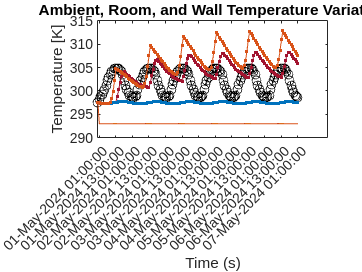

if exist('bldgSimRes','var')
    plotTimeSeriesTempRoomWallAmbient(SimlogData=bldgSimRes,...
                                      Duration=dateTimeVec,...
                                      PlotXAxisParts=12); 
end

Plot the heating and cooling requirement analysis summary.

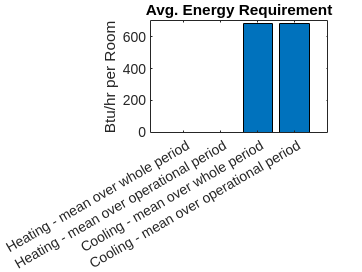

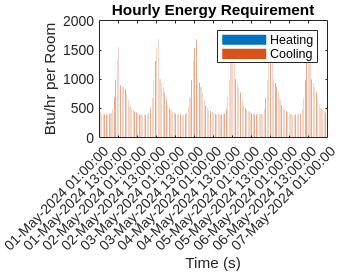

if roomModelOption == "roomPhysicsOptions.requirements" && exist('bldgSimRes','var')
    plotHeatCoolingRequirementAnalysisOutput(SimlogData=bldgSimRes,...
                                             Duration=dateTimeVec,...
                                             PlotXAxisParts=12);
end

The mean value of cooling and heating requirement is a good indication of the heat pump capacity required for actual operation.

### Visualize Building Temperature

showPlotForBuildingT = false;

You can also plot solar data by setting the above drop down to `Display Plot`.

if showPlotForBuildingT && exist('bldgSimRes','var')
    buildingDataWithTemp = getBuildingRoomTemperatureData(Building=apartment3D,...
                                                          SimlogData=bldgSimRes);
    count = 1;
    for nHrs = 1:length(dateTimeVec)
        figure(count)
        plot3DlayoutBuilding(Building=buildingDataWithTemp,...
                             PlotViewDirection=viewingAngle,...
                             ColorScheme="temperature",...
                             Hour=nHrs);
        title(strcat(geoLocation.Row,', Date/Time :',string(dateTimeVec(1,nHrs))));
        count = count + 1;
    end
end